**Beta**

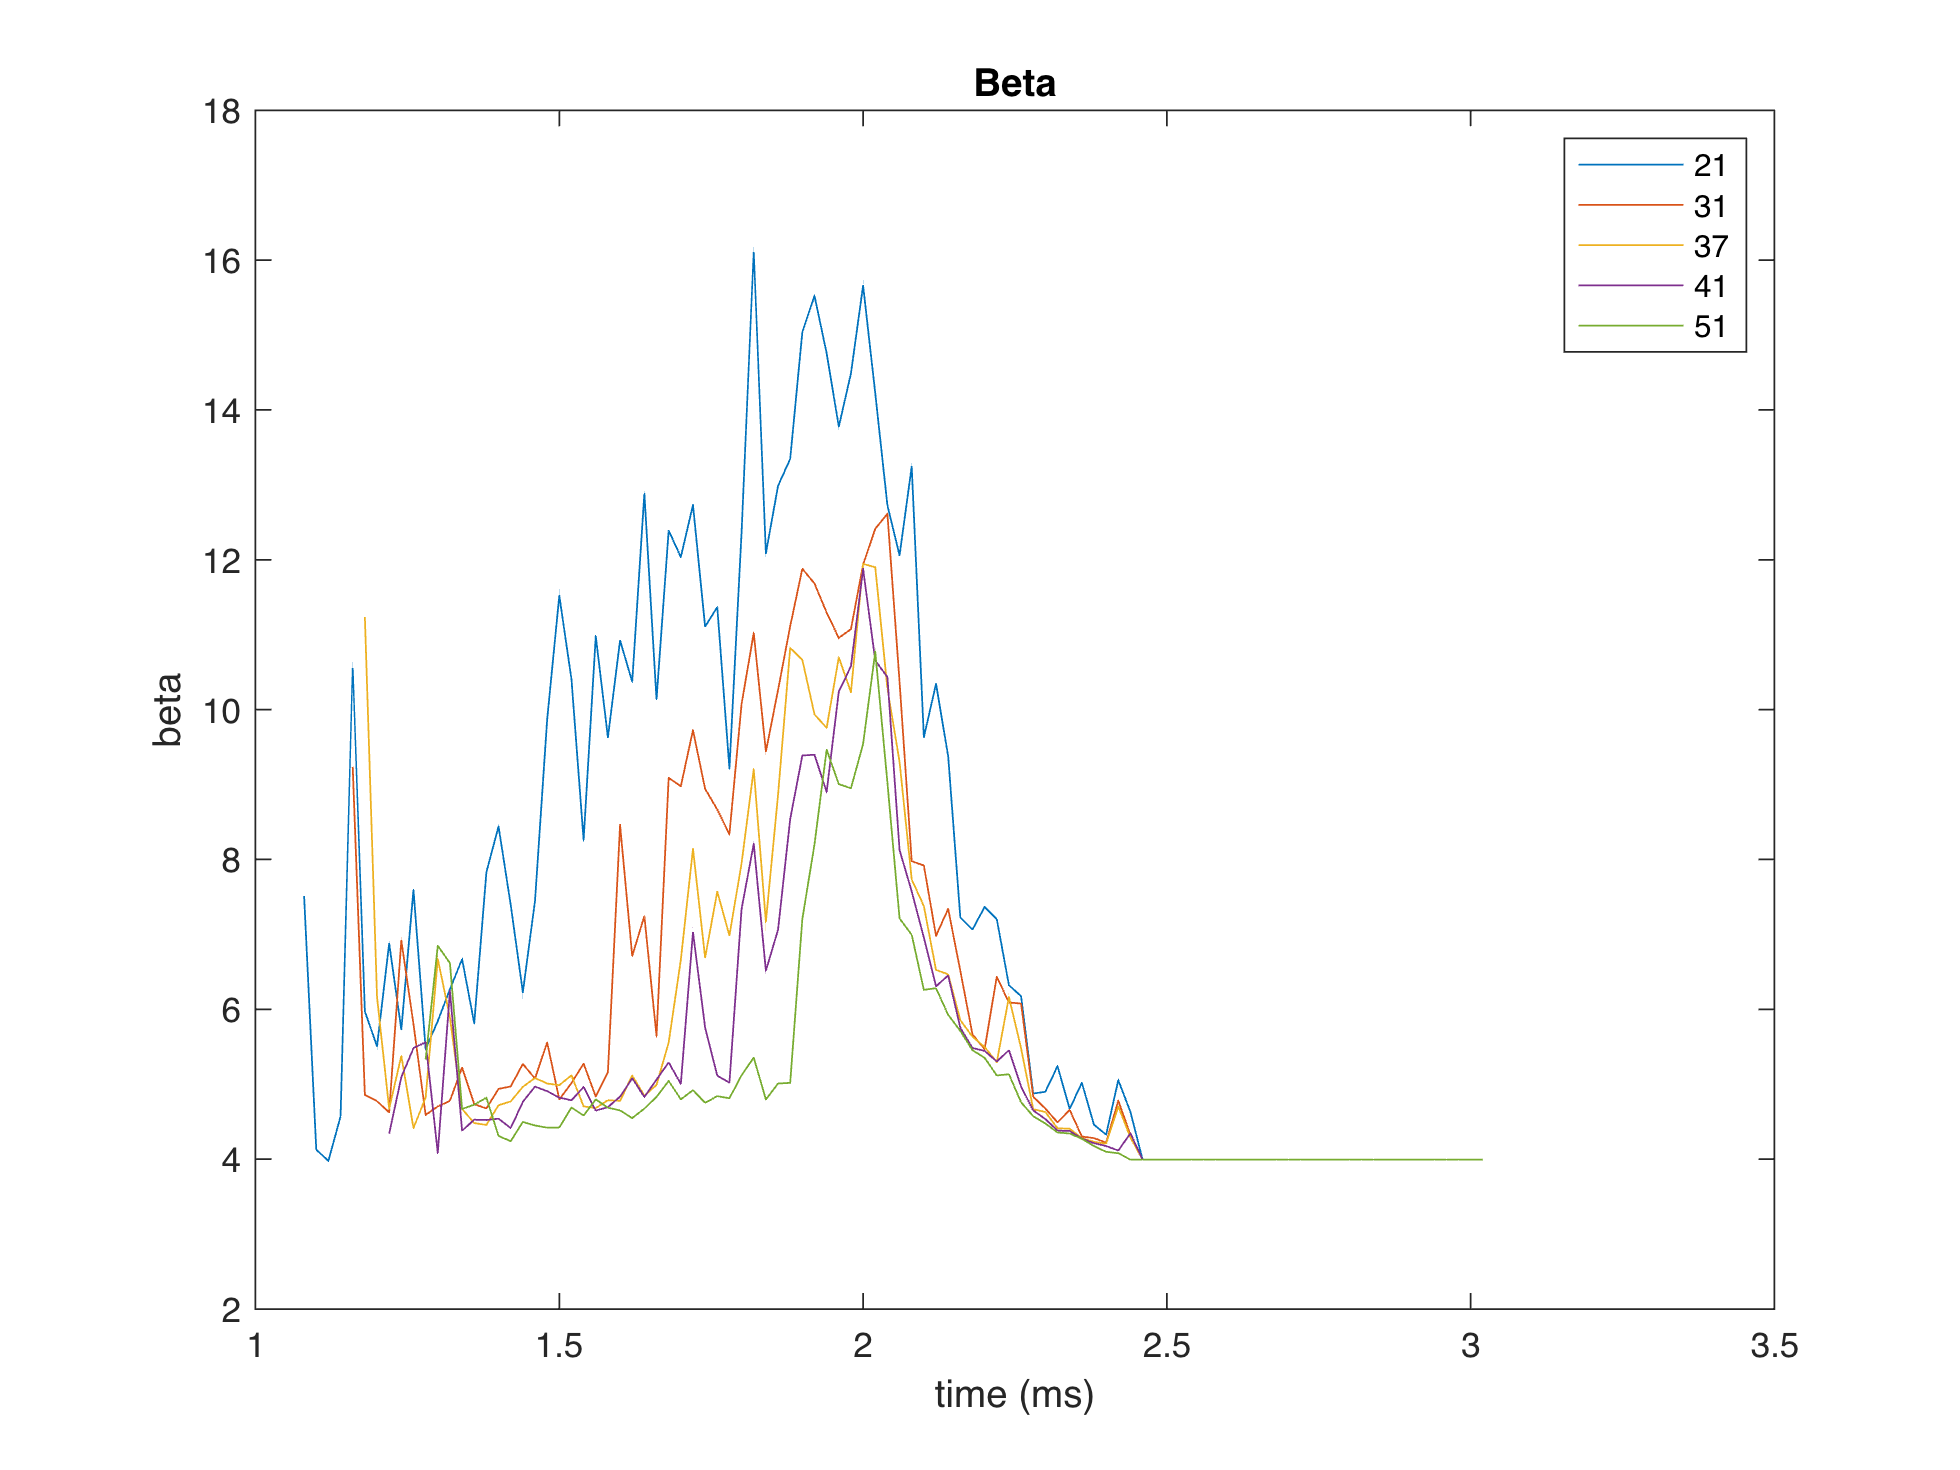

fpms = 50; %-- frames per millisecond
totalTime = size(experiment1, 3)/fpms;
msPerFrame = 1/fpms;
micronsPerXPixel = 13.5;
micronsPerZPixel = 50;
timeSmoothing = 3;
smoothing = [21 31 37 41 51];

threshold = 0.985;
betas = [{} {} {} {} {}];

for i=1:length(smoothing)
    current = SmoothExperiment(experiment1,timeSmoothing,threshold, smoothing(i), smoothing(i));
    scaled = ScaleImage(current,micronsPerZPixel/micronsPerXPixel);
    [Area,Perimeter,Velocity,Beta] = GetParameters(scaled);
    betas(i) = {Beta};
end

timeLine = (1:size(experiment1,3)) / fpms;

for i=1:length(smoothing)
    plot(timeLine,betas{i});
    hold on;
end
hold off;
title("Beta");
xlabel("time (ms)");
ylabel("beta");
legend("21", "31", "37", "41", "51");